# Exercise 1 Part B - Use Imported Truth Data to Generate Truth Trajectories for Simulation

Now that we have imported our truth data in the format that our simulation will expect, let's create truth trajectories from this data and visualize it on the globe before we setup the rest of the simulation.

Load the table we generated from the trackingDataImporter App

load('TruthData.mat','truthData')

Take the relevant data from one of the targets and generate a truth trajectory, then plot it:

Position = truthData{4}.Position;
Time = seconds(truthData{4}.Time);

**Step 1 - Create a trajectory for one target and plot on the trackingGlobeViewer to Visualize**

**Directions:**

Below, please create a variable 'traj' that holds the trajectory generated using 'geoTrajectory'. Use the "Position" and "Time" variables from above as inputs:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc geoTrajectory" in the Command Window to find the documentation page for this function
% WRITE YOUR CODE BELOW THIS LINE:

% Generate Trajectory
traj = geoTrajectory(Position,Time);


Create a trackingScenario to visualize the trajectory

scenario = trackingScenario(IsEarthCentered=true);

Create Platform that follows above trajectory

platform(scenario,Trajectory=traj);

Create the viewer to enable visualization:

mapOrigin = [42.39423231362 -70.95934958874 0]; 
mapViewer = trackingGlobeViewer('ReferenceLocation',mapOrigin,'Basemap','streets-dark');
campos(mapViewer, mapOrigin + [0 -0.4 1e5]);
drawnow;
plotScenario(mapViewer,scenario);

Take snapshot of viewer

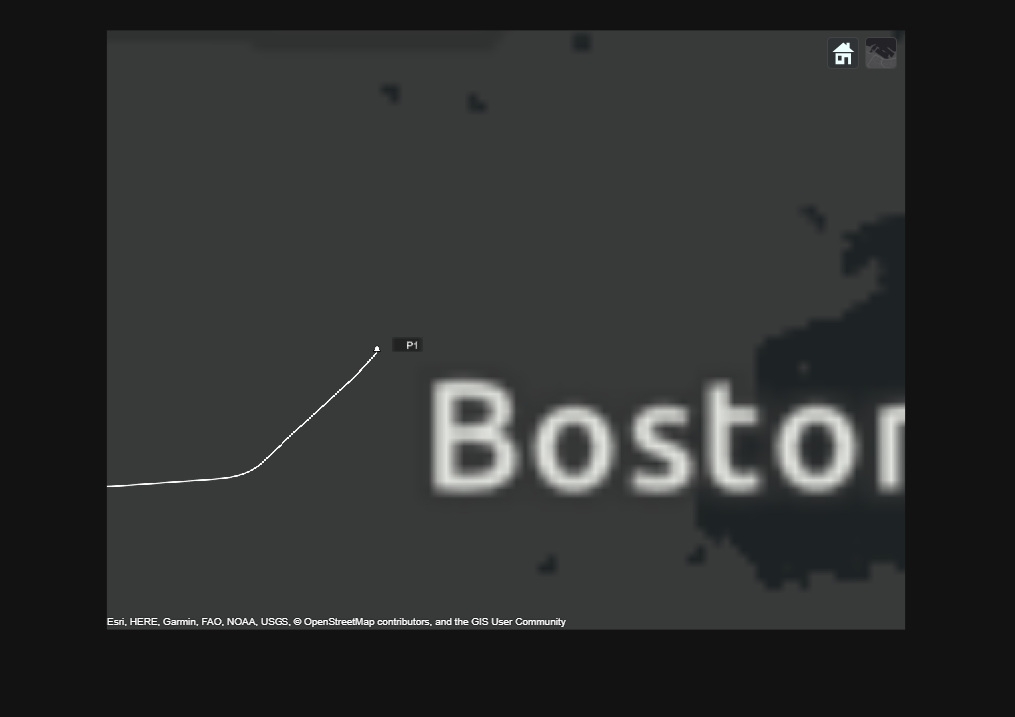

snapshot(mapViewer)

**Step 2 - Loop through each target and generate a trajectory for each**

Just run the code this time

scenario = trackingScenario(IsEarthCentered=true);
for i = 1:numel(truthData)
    % Geo Trajectory - isEarthCentered = true
    Pos = truthData{i}.Position;
    time = seconds(truthData{i}.Time);
        
    % Generate Trajectory 
    traj = geoTrajectory(Pos,time);

    % Create Platform that follows above trajectory 
    platform(scenario,Trajectory=traj);
end

Repeat steps from above to visualize

mapOrigin = [42.39423231362 -70.95934958874 0]; 
mapViewer = trackingGlobeViewer('ReferenceLocation',mapOrigin,'Basemap','streets-dark');
campos(mapViewer, mapOrigin + [0 -0.4 1e5]);
drawnow;
plotScenario(mapViewer,scenario);

Take snapshot of viewer

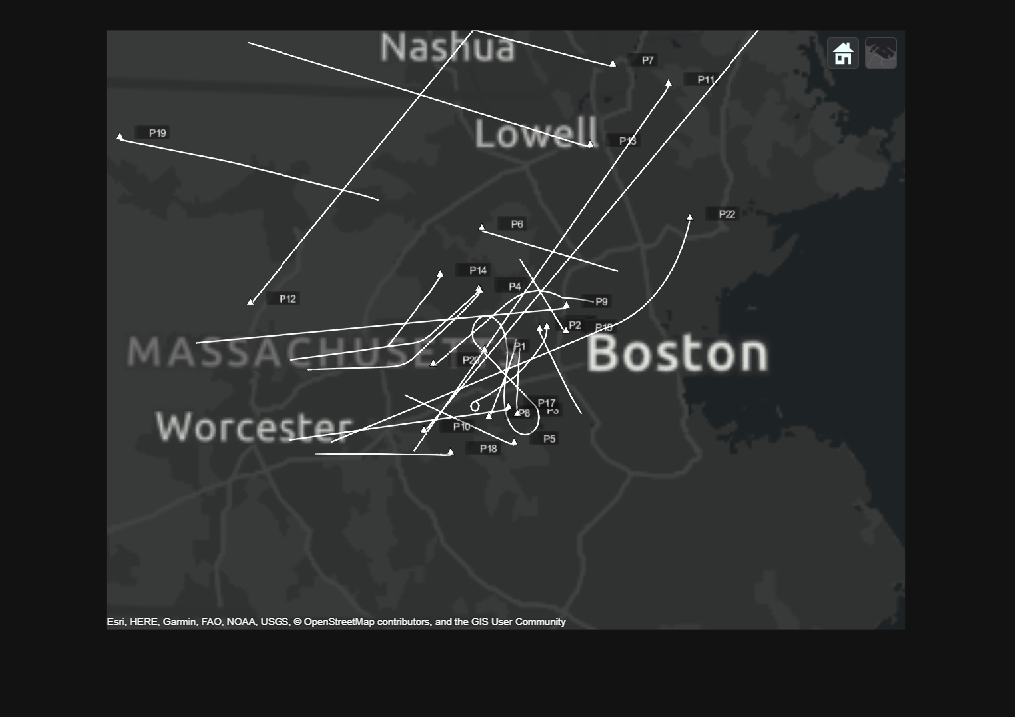

pause(1)
snapshot(mapViewer)